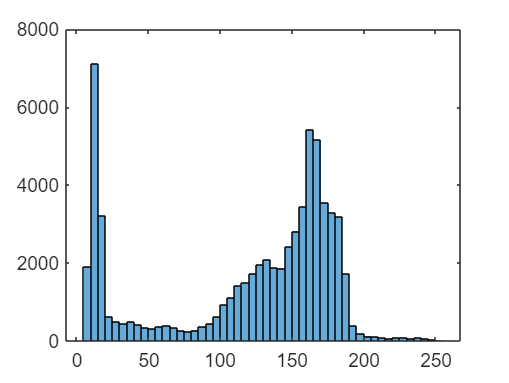

clear all
clc
i=importdata("cameraman.tif");
histogram(i)

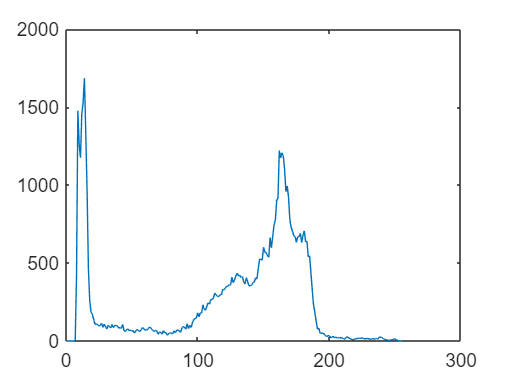

[value,loc]=imhist(i);
plot(loc,value);

## Moving Average Filter

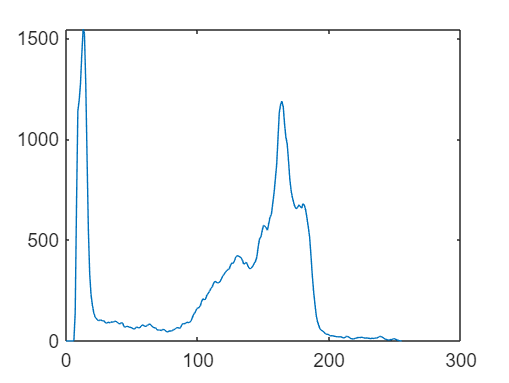

for i=2:255
    value(i)=(value(i-1)+value(i)+value(i+1))/3;
end
plot(loc,value);


for i=2:length(loc)-1
    if value(i)>value(i-1) && value(i)>value(i+1)
        s(i)=loc(i+1);
    end 
end


## Initial Peaks 

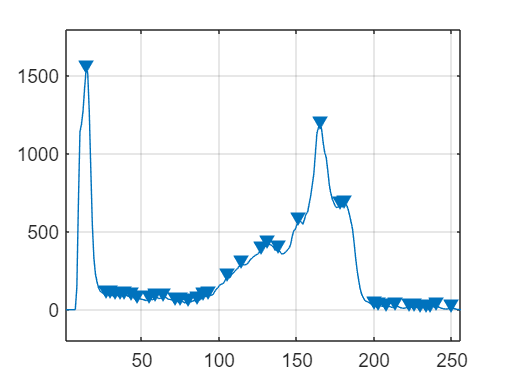

[h,s]=findpeaks(value);
findpeaks(value)

p=length(findpeaks(value))

p = 37

e=0.9;

## Peak Searching


for i=2:p
    xk=s(i)*ones(1,i-1);
    yk=h(i)*ones(1,i-1);
    
    del_xk=xk-(s(1:i-1))';
    del_yk=abs(yk-(h(1:i-1))');
    L=xk-(yk.*del_xk)./e+del_yk; 
    L1(i-1)=min(L);
end
L2=min(L1);
L2

L2 = -1.9879e+05

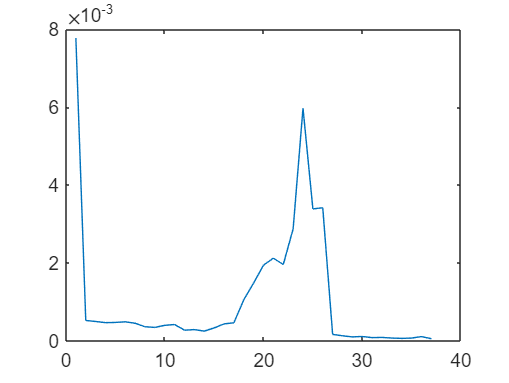

L3=[(L2)*ones(1,p)];
c=(h'./(s'-L3));
plot(c)

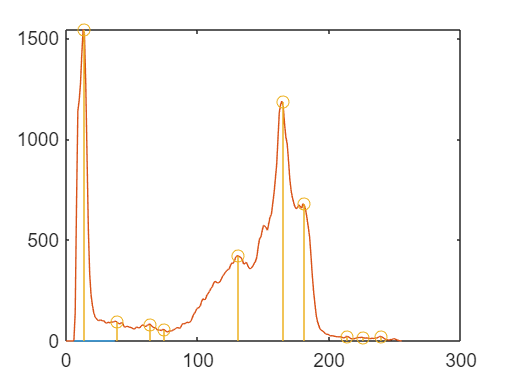

v1=[];
p1=[];
[p,v]=findpeaks(c);

if c(1)>c(2)
    v=[1,v];
end
if c(end)>c(end-1)
    v=[v,length(c)];
end

plot(c);
for i=1:length(v)
    s_loc(i)=s(v(i));
end 
hold on
plot(loc,value)
stem(s_loc,value(s_loc))
hold off